## 线性相关

相关性量化了两个变量之间线性关系的强度。

- 当两个变量之间没有相关性时，变量的值不会出现同步增加或减少的趋势。

- 然而，两个不相关的变量不一定独立，因为它们之间可能存在非线性关系。

- 您可以使用线性相关来调查变量之间是否存在线性关系，而无需对数据假设或拟合特定模型。

## 协方差

协方差以相对于其方差的单位量化两个变量之间线性关系的强度。

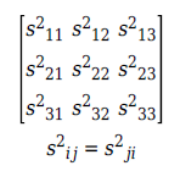

${s^2 }_{\mathrm{ij}}$ 是数据的第I列和第j列之间的样本协方差。因为计数矩阵包含三列，所以协方差矩阵是3乘3的

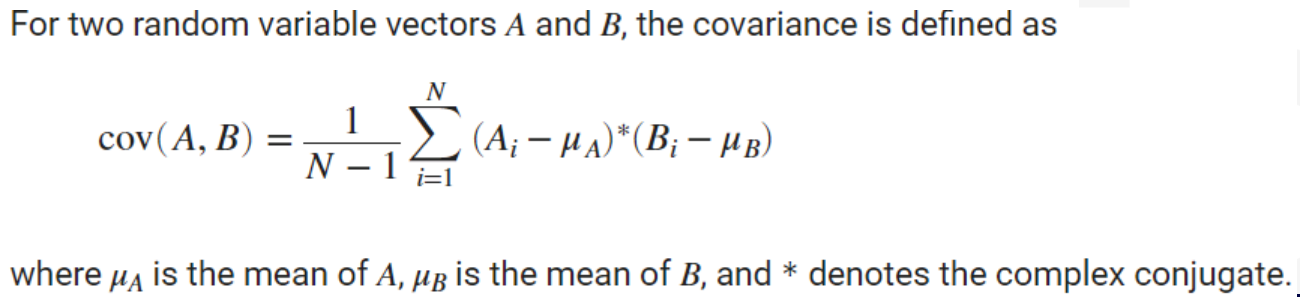

[https://ww2.mathworks.cn/help/matlab/ref/cov.html#buo3tdl-1](https://ww2.mathworks.cn/help/matlab/ref/cov.html#buo3tdl-1)

**使用 MATLAB 的 **`cov`**函数计算数据矩阵（每列代表一个独立量）的样本协方差矩阵。**

load count.dat
% 计算该数据的协方差矩阵：
cov = cov(count);

## 相关系数

`corrcoef`函数为数据矩阵（每列代表一个独立量）生成样本相关系数矩阵。相关系数的范围从 -1 到 1，其中：

- 接近 1 的值表明数据列之间存在正线性关系。

- 接近 -1 的值表明一列数据与另一列数据存在负线性关系（反相关）。

- 接近或等于 0 的值表明数据列之间没有线性关系。

使用 `corrcoef`计算相关系数：

load count.dat
%Calculate the correlation coefficients for this data:
corr=corrcoef(count);
corr

corr =    1.000000000000000   0.933117916613626   0.959931702496072
   0.933117916613626   1.000000000000000   0.955300760020290
   0.959931702496072   0.955300760020290   1.000000000000000


由于所有相关系数都接近 1，表明 count 矩阵中每对数据列之间都存在强正相关关系。